**使用极坐标初始化编队形状**

单位为弧度，米

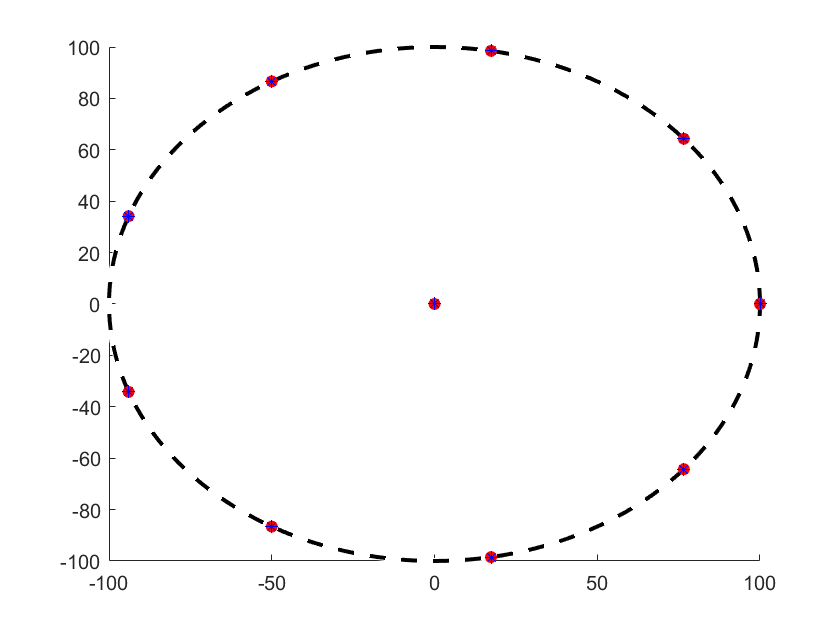

formation = [
    0	0
    0	100
    0.698131700797732	100
    1.39626340159546	100
    2.09439510239320	100
    2.79252680319093	100
    3.49065850398866	100
    4.18879020478639	100
    4.88692190558412	100
    5.58505360638185	100
    ];
[sender_vec_table,ideal_pos,real_pos] = init(formation,'true');
hold on
viscircles([0,0],100,'Color','k','LineStyle','--');
scatter(ideal_pos(:,1), ideal_pos(:,2),'filled','r');
scatter(real_pos(:,1), real_pos(:,2),'*','b');

**确定迭代的参数**

NUM_STEPS = 100;
senders = [1,3,5];
noise = "false";
num_plane = 10;

**开始迭代**

pos_log = zeros(10,2,0);

for iter = 1:NUM_STEPS
    %添加噪声
    if(noise == "true")
        real_pos = real_pos + rand(size(init_pos))*5;
    end
    
    recieved_vec = send(senders,real_pos);
    get_esti_pos(senders,recieved_vec,formation,sender_vec_table)
    move = (ideal_pos - esti_pos)*0.1;
    move(isnan(move)) = 0;
    real_pos = real_pos+move;
    
    pos_log = cat(3,pos_log,reshape(real_pos,10,2,1));
end

ans =        NaN       NaN
  100.0000   -0.0000
       NaN       NaN
   17.3648   98.4808
       NaN       NaN
  -93.9693   34.2020
  -93.9693  -34.2020
  -50.0000  -86.6025
   17.3648  -98.4808
   76.6044  -64.2788


ans =        NaN       NaN
   99.3443   -0.3752
       NaN       NaN
   18.0446   97.4713
       NaN       NaN
  -94.6007   34.2173
  -92.7691  -34.2852
  -49.1422  -86.0551
   17.4040  -97.8809
   74.7957  -63.2377


ans =        NaN       NaN
   98.6782   -0.7498
       NaN       NaN
   18.6868   96.4707
       NaN       NaN
  -95.2361   34.2386
  -91.5686  -34.3566
  -48.2965  -85.5048
   17.4411  -97.2871
   73.0012  -62.1933


ans =        NaN       NaN
   98.0015   -1.1235
       NaN       NaN
   19.2955   95.4794
       NaN       NaN
  -95.8754   34.2657
  -90.3679  -34.4162
  -47.4629  -84.9517
   17.4764  -96.6994
   71.2212  -61.1458


ans =        NaN       NaN
   97.3139   -1.4962
       NaN       NaN
   19.8743   94.4978
       NaN       NaN
  -96.5185   34.2985
  -89.1673  -34.4640
  -46.6413  -84.3961
   17.5097  -96.1177
   69.4556  -60.0953


ans =        NaN       NaN
   96.6154   -1.8678
       NaN       NaN
   20.4261   93.5262
       NaN       NaN
  -97.1653   34.3368
  -87.9670  -34.5002
  -45.8315  -83.8381
   17.5412  -95.5419
   67.7048  -59.0418


ans =        NaN       NaN
   95.9057   -2.2381
       NaN       NaN
   20.9537   92.5647
       NaN       NaN
  -97.8156   34.3805
  -86.7671  -34.5246
  -45.0334  -83.2779
   17.5709  -94.9719
   65.9689  -57.9856


ans =        NaN       NaN
   95.1847   -2.6070
       NaN       NaN
   21.4597   91.6134
       NaN       NaN
  -98.4692   34.4293
  -85.5678  -34.5374
  -44.2468  -82.7157
   17.5988  -94.4076
   64.2480  -56.9268


ans =        NaN       NaN
   94.4522   -2.9743
       NaN       NaN
   21.9463   90.6723
       NaN       NaN
  -99.1262   34.4833
  -84.3694  -34.5386
  -43.4717  -82.1516
   17.6251  -93.8490
   62.5422  -55.8655


ans =        NaN       NaN
   93.7079   -3.3398
       NaN       NaN
   22.4153   89.7416
       NaN       NaN
  -99.7864   34.5421
  -83.1719  -34.5282
  -42.7078  -81.5859
   17.6497  -93.2960
   60.8519  -54.8018


ans =        NaN       NaN
   92.9518   -3.7033
       NaN       NaN
   22.8687   88.8212
       NaN       NaN
 -100.4497   34.6058
  -81.9757  -34.5063
  -41.9552  -81.0186
   17.6727  -92.7484
   59.1771  -53.7360


ans =        NaN       NaN
   92.1836   -4.0647
       NaN       NaN
   23.3080   87.9110
       NaN       NaN
 -101.1159   34.6741
  -80.7808  -34.4729
  -41.2135  -80.4500
   17.6942  -92.2063
   57.5180  -52.6681


ans =        NaN       NaN
   91.4031   -4.4237
       NaN       NaN
   23.7347   87.0111
       NaN       NaN
 -101.7850   34.7470
  -79.5876  -34.4282
  -40.4828  -79.8801
   17.7141  -91.6696
   55.8749  -51.5985


ans =        NaN       NaN
   90.6102   -4.7802
       NaN       NaN
   24.1500   86.1213
       NaN       NaN
 -102.4569   34.8243
  -78.3960  -34.3721
  -39.7628  -79.3091
   17.7326  -91.1381
   91.2915  -73.2160


输入参数的数目不足。

出错 get_esti_pos (第 24 行)
            esti_pos = old;

hold on
viscircles([0,0],100,'Color','k','LineStyle','--');
scatter(ideal_pos(:,1), ideal_pos(:,2),'filled','r');
scatter(real_pos(:,1), real_pos(:,2),'o','b');

for index = 1:num_plane
    plot(reshape(pos_log(index,1,:),1,NUM_STEPS),reshape(pos_log(index,2,:),1,NUM_STEPS));
end

viscircles([0,0],r_avg,'Color','y','LineStyle','--');
scatter(real_pos(:,1), real_pos(:,2),'*','g');
hold off